# **STEP_01:**  Explore a simple cantilever - **STATIC deflection test**

Let's get familiar with the **Flexible Beam block** in Simscape Multibody

- [https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

And what better way, than to model and VERIFY the behavior of a simple cantilever beam 

**Objective:**

- Compute the analytic deflection of a cantilever subject to a combined load made up of a uniformly distributed load (it's self weight) AND a point load applied at it's tip.

- Compare this deflection against Simscape Multibody model

So here is the Cantilever system that we're going to focus on - and note the orientation of the **Inertial reference frame**.

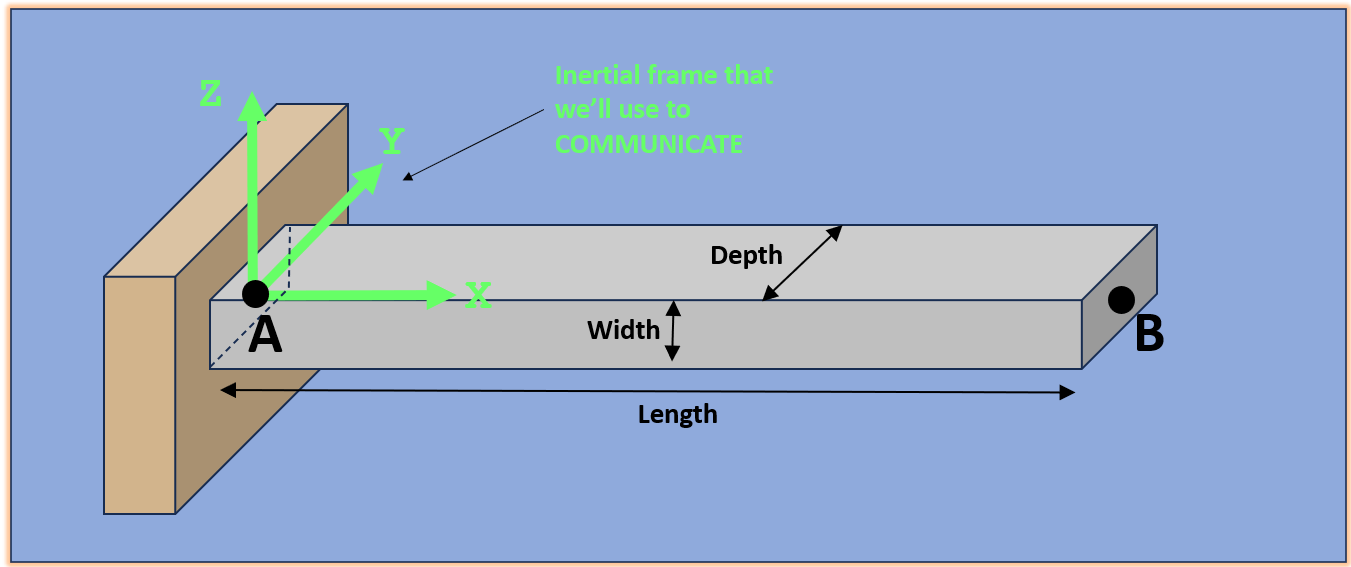

## Clear the workspace

clear

## Define the Beam (we'll eventually call it a COLUMN)

We're going to represent our cantilever using the [**Flexible Rectangular Beam**](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html) block provided by Simscape Multibody.  

This block uses a **body fixed frame** to allow us to characterize it's geometry .... and it just so happens that this body fixed frame is NOT orientated in the same direction as our preferred co-ordinate system.  The **body fixed frame** used by the [**Flexible Rectangular Beam**](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html) block has the orientation shown below

So ? - So let's characterize our beam using this **body fixed frame.** We've written a custom data container that allows us to store properties of the beam according to this local body fixed frame, see:

- [`bh_create_column_OBJ`](matlab:  edit  bh_create_column_OBJ)

- [`bh_flex_column_CLS`](matlab: edit bh_flex_column_CLS)

col_OBJ              = bh_create_column_OBJ(Width=1/1000, Depth=25.4/1000, Length=300/1000, density=7800);
col_OBJ.damp_K_coeff = 1e-2; 
col_OBJ.num_eles     = 4;
% assert(0==mod(col_OBJ.num_eles,2), "###_ERROR:  pick an EVEN number of elements");

And we'll compute(for comparison) the stiffness at the TIP for a POINT load

col_OBJ.BC_case      = "CANTILEVER"; % "FIXED_FIXED_WITH_SWAY";

So what attributes do we have

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 1.0000e-03
          DEPTH_y: 0.0254
         LENGTH_z: 0.3000
          density: 7800
      E_GPa_Young: 200
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 0.0100
       damp_ratio: 0
         num_eles: 4
    num_ret_modes: 5
          BC_case: "CANTILEVER"
             mass: 0.0594
              vol: 7.6200e-06
               Ix: 1.3656e-09
               Iy: 2.1167e-12
               Kx: 47.0370
             area: 2.5400e-05


## Define the Environment

g_vector = [0, 0, -9.80665];

# Calculate the analytic deflection of a cantilever

Let:

- $q$ = uniform load on the beam (force per unit length)

- $L$ = length of the beam

- $E$ = modulus of elasticity

- $I$ = area moment of inertia of cross section

NOTE:

-  the tip deflection of a cantilever with a uniformly distributed load is $\delta =\;\frac{q\ldotp L^4 }{8\ldotp E\ldotp I}$   (REFERENCE:  [`HERE`](https://en.wikipedia.org/wiki/Deflection_%28engineering%29))

-  the tip deflection of a cantilever with a TIP load $F$ is    $\delta =\;\frac{F\ldotp L^3 }{3\ldotp E\ldotp I}$   (REFERENCE:  [`HERE`](https://en.wikipedia.org/wiki/Deflection_%28engineering%29))

fh_def_dist_load = @(q)  q * col_OBJ.LENGTH_z^4 / (8 * col_OBJ.E_GPa_Young*1e9 *col_OBJ.Iy);
fh_def_tip_load  = @(F)  F * col_OBJ.LENGTH_z^3 / (3 * col_OBJ.E_GPa_Young*1e9 *col_OBJ.Iy);

## Static deflections

**ATTENTION:**

- set the damping to a higher value so that you see an OVERDAMPED response (i.e. very few oscillations)

**Deflection of self weight**

q_applied       = 9.8065*col_OBJ.mass/col_OBJ.LENGTH_z; % (N/m)
def_self_weight = fh_def_dist_load(q_applied)           % (m)

def_self_weight = 0.0046

**Deflection of downwards TIP load**

F_applied       = 1;                         % (N)
def_point_load  = fh_def_tip_load(F_applied) % (m)

def_point_load = 0.0213

**TOTAL deflection**

def_total = def_self_weight + def_point_load

def_total = 0.0259

## Now compare against the Simulink model

open_system("bh_cantilever_STATIC_test.slx")

When the Simulink model opens:

- Click the RUN icon to run the simulation

- Double click on the scope block (TIP_DEFLECTION) to observe the tip deflection

NOTE the following:

- from $\left(0\le t\le 3\right)$ we observe the tip deflection due just to the self weight of the cantilever

- from $\left(3\le t\le 6\right)$ we observe the tip deflection due to self_weight AND a static load applied to the tip

- from $\left(6\le t\le 10\right)$ we observe the tip deflection due just to the self weight of the cantilever

How do these deflection values compare to the analytic values computed using Engineering Beam theory ?